# === Frequency Analysis ===

close all; clear; clc

distanceConversion = 0.02;
forceConversion = 0.0000478305936073059;
experimentTime = 30; % seconds

## == Read Data from file ==

filename = "TPU-16.05.25/arduino_dataPERIODIC.csv";
rawData = readmatrix(filename);

## == Extract Data ==

distance = rawData(:, 1) * distanceConversion

distance =     0.0600
   -0.2000
   -0.4800
   -0.2000
    0.1000
    0.3800
    0.3400
    0.0600
   -0.2400
   -0.4600


force = rawData(:, 2) * forceConversion

force =     1.0069
   -0.0029
   -1.0319
   -1.4997
   -0.7787
    0.2803
    1.1037
    0.8559
   -0.1806
   -1.1875


## == Frequency Analysis Preperation ==

%% Define sampling rate
close all;

sampleSize = size(force);
L = sampleSize(1);

fe = L / experimentTime % sampling frequency

fe = 12.3667

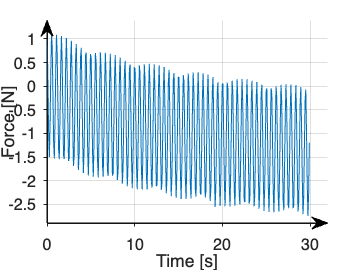


h = 1/fe; % sampling period

data = force - mean(force);
fdata = fft(data);

N = length(data);
f = (0:N-1) * (fe / N);   % Frequency vector in Hz
t = (0:N-1) / fe;  % Time vector in seconds


%============ Periodic Force Experiment over 30 seconds ================================================================================================================

figure(1)
plot(t, force)

%title('Periodic Force Experiment over 30 seconds')

xlim([0 32]);  % Only show x >= 0
ylim([-2.9 1.4]);  % Only show y >= 0
%yticks(0:10:150);        % Adds a line every 0.5 units

grid on;

% Shift plot area up
ax = gca;
pos = ax.Position;
pos(2) = pos(2) + 0.07;
pos(4) = pos(4) - 0.07;
set(ax, 'Position', pos);

% Move x-label down
xl = xlabel('Time [s]');
set(xl, 'Units', 'normalized');
xlPos = get(xl, 'Position');
xlPos(2) = xlPos(2) - 0.08;
set(xl, 'Position', xlPos);

% Move y-label left
yl = ylabel('Force [N]');
set(yl, 'Units', 'normalized');
ylPos = get(yl, 'Position');
ylPos(1) = ylPos(1) - 0.05;
set(yl, 'Position', ylPos);

% Add axis arrows
annotation('arrow', [pos(1), pos(1) + pos(3)], [pos(2), pos(2)]);
annotation('arrow', [pos(1), pos(1)], [pos(2), pos(2) + pos(4)]);

set(gca, 'TickDir', 'out');      % or 'none' to remove completely
set(gca, 'Box', 'off');          % removes top and right axes

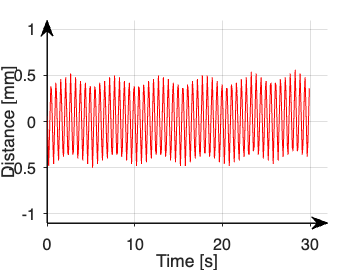


%============ Periodic Distance Experiment over 30 seconds ================================================================================================================

figure(10)
plot(t, distance, 'r')

%title('Periodic Distance Experiment over 30 seconds')

xlim([0 32]);  % Only show x >= 0
ylim([-1.1 1.1]);  % Only show y >= 0
%yticks(0:10:150);        % Adds a line every 0.5 units

grid on;

% Shift plot area up
ax = gca;
pos = ax.Position;
pos(2) = pos(2) + 0.07;
pos(4) = pos(4) - 0.07;
set(ax, 'Position', pos);

% Move x-label down
xl = xlabel('Time [s]');
set(xl, 'Units', 'normalized');
xlPos = get(xl, 'Position');
xlPos(2) = xlPos(2) - 0.08;
set(xl, 'Position', xlPos);

% Move y-label left
yl = ylabel('Distance [mm]');
set(yl, 'Units', 'normalized');
ylPos = get(yl, 'Position');
ylPos(1) = ylPos(1) - 0.05;
set(yl, 'Position', ylPos);

% Add axis arrows
annotation('arrow', [pos(1), pos(1) + pos(3)], [pos(2), pos(2)]);
annotation('arrow', [pos(1), pos(1)], [pos(2), pos(2) + pos(4)]);

set(gca, 'TickDir', 'out');      % or 'none' to remove completely
set(gca, 'Box', 'off');          % removes top and right axes

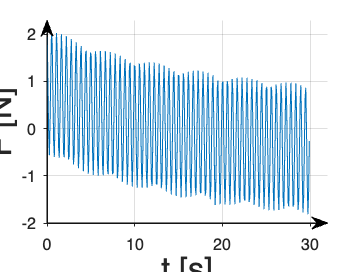


%============ Periodic Force Normalized ================================================================================================================

figure(2)
plot(t, data)

%title('Normalized Force Signal')

xlim([0 32]);  % Only show x >= 0
ylim([-2 2.3]);  % Only show y >= 0
%yticks(0:10:150);        % Adds a line every 0.5 units

grid on;

% Shift plot area up
ax = gca;
pos = ax.Position;
pos(2) = pos(2) + 0.07;
pos(4) = pos(4) - 0.07;
set(ax, 'Position', pos);

% Move x-label down
xl = xlabel('t [s]', 'FontSize', 20);
set(xl, 'Units', 'normalized');
xlPos = get(xl, 'Position');
xlPos(2) = xlPos(2) - 0.08;
set(xl, 'Position', xlPos);

% Move y-label left
yl = ylabel('F [N]', 'FontSize', 20);
set(yl, 'Units', 'normalized');
ylPos = get(yl, 'Position');
ylPos(1) = ylPos(1) - 0.05;
set(yl, 'Position', ylPos);

% Add axis arrows
annotation('arrow', [pos(1), pos(1) + pos(3)], [pos(2), pos(2)]);
annotation('arrow', [pos(1), pos(1)], [pos(2), pos(2) + pos(4)]);

set(gca, 'TickDir', 'out');      % or 'none' to remove completely
set(gca, 'Box', 'off');          % removes top and right axes

exportgraphics(gcf, 'figures/NormalizedForce.png', 'Resolution', 600);  % High quality

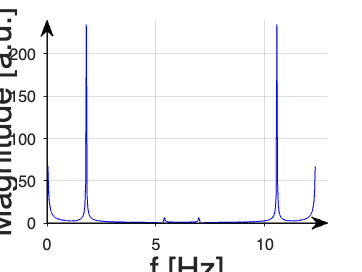


%============ FFT of Unfiltered Force Signal ================================================================================================================

figure(3)

plot(f, abs(fft(data)), 'b');
%title('FFT of Unfiltered Force Signal')

xlim([0 12.9]);  % Only show x >= 0
ylim([0 240]);  % Only show y >= 0
%yticks(0:10:150);        % Adds a line every 0.5 units

grid on;

% Shift plot area up
ax = gca;
pos = ax.Position;
pos(2) = pos(2) + 0.07;
pos(4) = pos(4) - 0.07;
set(ax, 'Position', pos);

% Move x-label down
xl = xlabel('f [Hz]', 'FontSize', 20);
set(xl, 'Units', 'normalized');
xlPos = get(xl, 'Position');
xlPos(2) = xlPos(2) - 0.08;
set(xl, 'Position', xlPos);

% Move y-label left
yl = ylabel('Magnitude [a.u.]', 'FontSize', 20);
set(yl, 'Units', 'normalized');
ylPos = get(yl, 'Position');
ylPos(1) = ylPos(1) - 0.05;
set(yl, 'Position', ylPos);

% Add axis arrows
annotation('arrow', [pos(1), pos(1) + pos(3)], [pos(2), pos(2)]);
annotation('arrow', [pos(1), pos(1)], [pos(2), pos(2) + pos(4)]);

set(gca, 'TickDir', 'out');      % or 'none' to remove completely
set(gca, 'Box', 'off');          % removes top and right axes

exportgraphics(gcf, 'figures/UnfilteredFFT.png', 'Resolution', 600);  % High quality


% peak @ 55

fdata(54)

ans = -46.5406 - 2.8974i

fdata(55)

ans = 2.3460e+02 + 1.7040e+00i

fdata(56)

ans = 33.7549 - 0.2975i


% conjugate peak @ 318

fdata(319)

ans = -46.5406 + 2.8974i

fdata(318)

ans = 2.3460e+02 - 1.7040e+00i

fdata(317)

ans = 33.7549 + 0.2975i


middlePoint = L/2;
middlePointRound = round(middlePoint);

% 4th order low-pass filter with wn = 56 (cutoff frequency)

[B, A] = butter(4, 56/middlePoint)

B =     0.0189    0.0758    0.1137    0.0758    0.0189


A =     1.0000   -1.5554    1.2604   -0.4768    0.0749



% filter signal

filteredSignal = filter(B, A, data);

%============ figure 4 ================================================================================================================

% figure(4)
% plot(filteredSignal);

fFilteredSignal = fft(filteredSignal);

%============ figure 5 ================================================================================================================

% figure(5)
% plot(abs(fFilteredSignal))

% high-pass filter -> @ 45 
[Bh, Ah] = butter(4, 45/middlePoint, 'high');
sum(Bh) % must be zero for high-pass

ans = 0

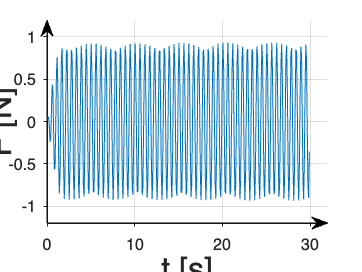


doubleFilteredSignal = filter(Bh, Ah, filteredSignal);

fDoubleFilteredSignal = fft(doubleFilteredSignal);


%============ Filtered and Normalized Force Signal ================================================================================================================

figure(6)
plot(t, doubleFilteredSignal)

%title('Filtered and Normalized Force Signal')

xlim([0 32]);  % Only show x >= 0
ylim([-1.2 1.2]);  % Only show y >= 0
%yticks(0:10:150);        % Adds a line every 0.5 units

grid on;

% Shift plot area up
ax = gca;
pos = ax.Position;
pos(2) = pos(2) + 0.07;
pos(4) = pos(4) - 0.07;
set(ax, 'Position', pos);

% Move x-label down
xl = xlabel('t [s]');
set(xl, 'Units', 'normalized', 'FontSize', 20);
xlPos = get(xl, 'Position');
xlPos(2) = xlPos(2) - 0.08;
set(xl, 'Position', xlPos);

% Move y-label left
yl = ylabel('F [N]', 'FontSize', 20);
set(yl, 'Units', 'normalized');
ylPos = get(yl, 'Position');
ylPos(1) = ylPos(1) - 0.05;
set(yl, 'Position', ylPos);

% Add axis arrows
annotation('arrow', [pos(1), pos(1) + pos(3)], [pos(2), pos(2)]);
annotation('arrow', [pos(1), pos(1)], [pos(2), pos(2) + pos(4)]);

set(gca, 'TickDir', 'out');      % or 'none' to remove completely
set(gca, 'Box', 'off');          % removes top and right axes

exportgraphics(gcf, 'figures/FilteredNormalizedForce.png', 'Resolution', 600);  % High quality

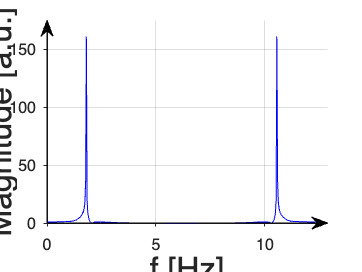


%============ FFT of Filtered Force Signal ================================================================================================================

figure(7)
plot(f, abs(fDoubleFilteredSignal), 'b')
%title('FFT of Filtered Force Signal')
xlim([0 12.9]);  % Only show x >= 0
ylim([0 175]);  % Only show y >= 0
%yticks(0:10:150);        % Adds a line every 0.5 units

grid on;

% Shift plot area up
ax = gca;
pos = ax.Position;
pos(2) = pos(2) + 0.07;
pos(4) = pos(4) - 0.07;
set(ax, 'Position', pos);

% Move x-label down
xl = xlabel('f [Hz]', 'FontSize', 20);
set(xl, 'Units', 'normalized');
xlPos = get(xl, 'Position');
xlPos(2) = xlPos(2) - 0.08;
set(xl, 'Position', xlPos);

% Move y-label left
yl = ylabel('Magnitude [a.u.]', 'FontSize', 20);
set(yl, 'Units', 'normalized');
ylPos = get(yl, 'Position');
ylPos(1) = ylPos(1) - 0.05;
set(yl, 'Position', ylPos);

% Add axis arrows
annotation('arrow', [pos(1), pos(1) + pos(3)], [pos(2), pos(2)]);
annotation('arrow', [pos(1), pos(1)], [pos(2), pos(2) + pos(4)]);

set(gca, 'TickDir', 'out');      % or 'none' to remove completely
set(gca, 'Box', 'off');          % removes top and right axes

exportgraphics(gcf, 'figures/FilteredFFT.png', 'Resolution', 600);  % High quality


% windowedSignal = data .* (hann(L)');
% 
% figure(6)
% plot(windowedSignal)
% 
% figure(7) 
% plot(abs(fft(windowedSignal)))